## Load Bbp data

bbp_files = dir('bbp_*.csv');

% Initialize an empty table
bbp_tbl = table();

% Loop through each file and append its contents
for i = 1:length(bbp_files)
    % Read the current CSV file
    tempTable = readtable(bbp_files(i).name);
    
    % Append to the combined table
    bbp_tbl = [bbp_tbl; tempTable]; % Concatenation
end

bbp_tbl = sortrows(bbp_tbl, 'date', 'ascend');
% Display the first 5 rows of the combined table
disp(bbp_tbl(1:min(5, height(bbp_tbl)), :));

## Plot Bbp data

range_bbp = [0 0.03]

range_bbp =          0    0.0300


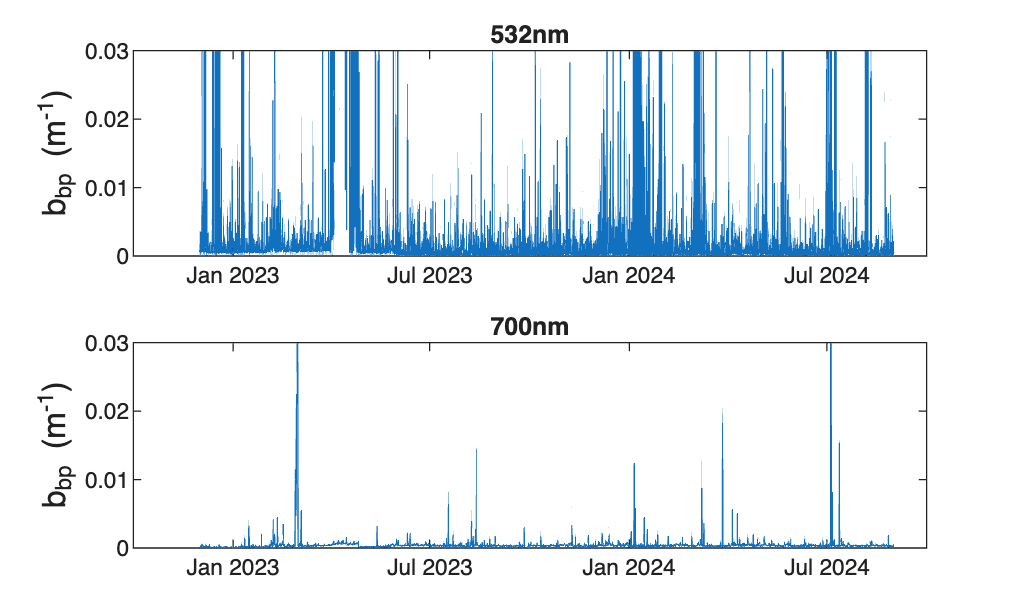


figure(1)
subplot(2,1,1)
    plot(bbp_tbl{:,1},bbp_tbl{:,2})
    title('532nm')
    ylabel('b_{bp} (m^{-1})','FontSize', 12)
    ylim(range_bbp) 
subplot(2,1,2)
    plot(bbp_tbl{:,1},bbp_tbl{:,3})
    title('700nm')
    ylabel('b_{bp} (m^{-1})','FontSize', 12)
    ylim(range_bbp) 

## Smooth data

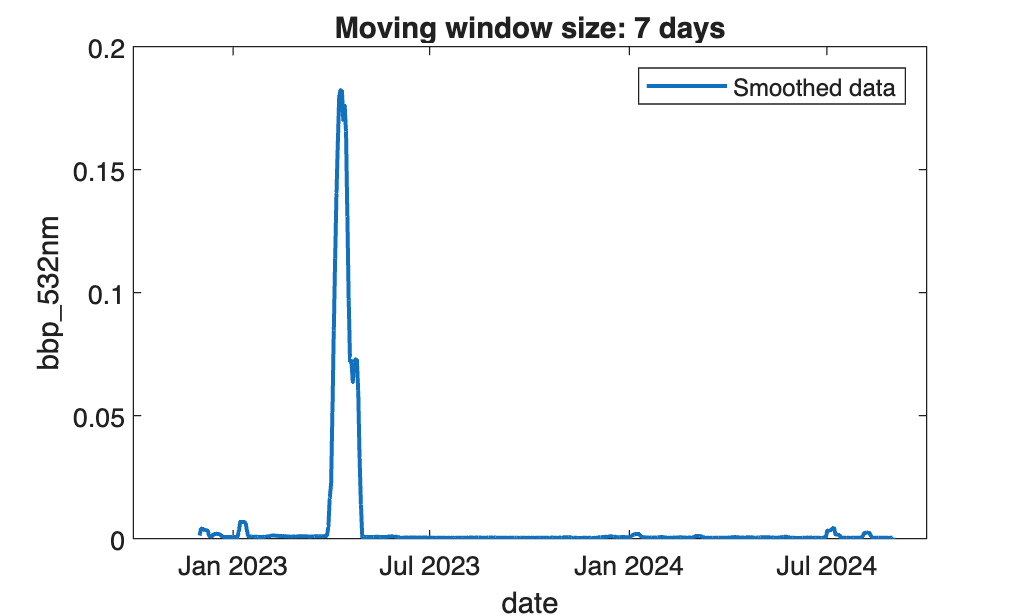

% Smooth input data
[smoothed532,winSize] = smoothdata(bbp_tbl(:,"bbp_532nm"),"movmean",days(7), ...
    SamplePoints=bbp_tbl.date);

% Display results
figure
plot(bbp_tbl.date,smoothed532.bbp_532nm,SeriesIndex=1,LineWidth=1.5, ...
    DisplayName="Smoothed data")
title("Moving window size: " + string(winSize));
legend
ylabel("bbp_532nm",Interpreter="none")
xlabel("date")

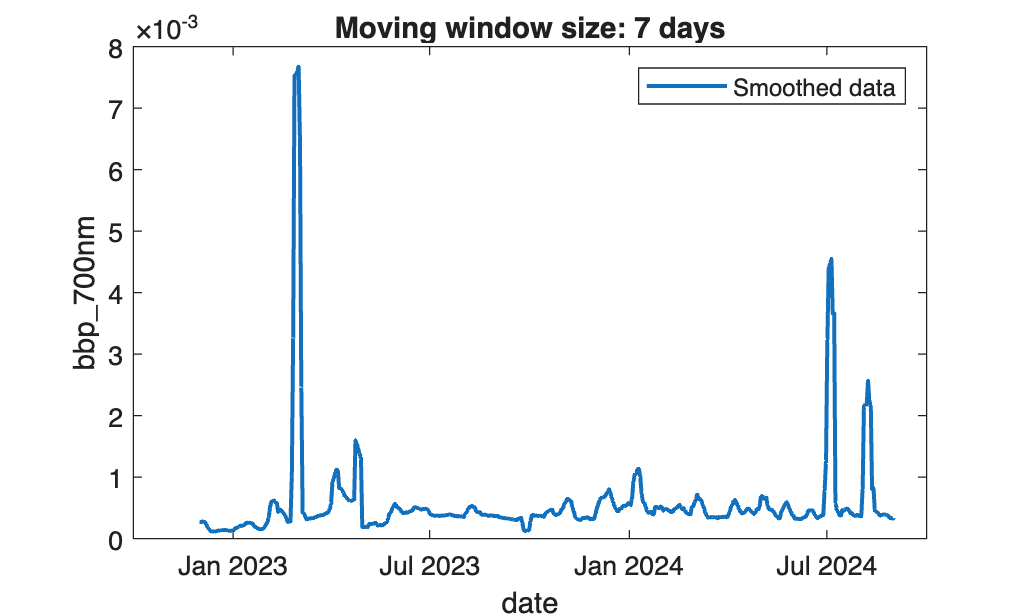

% Smooth input data
[smoothed700,winSize2] = smoothdata(bbp_tbl(:,"bbp_700nm"),"movmean",days(7), ...
    SamplePoints=bbp_tbl.date);

% Display results
figure
plot(bbp_tbl.date,smoothed700.bbp_700nm,SeriesIndex=1,LineWidth=1.5, ...
    DisplayName="Smoothed data")
title("Moving window size: " + string(winSize2));
legend
ylabel("bbp_700nm",Interpreter="none")
xlabel("date")

clear winSize2